clear all
close all
%%
load('Irr_PA_mon.mat');
load('load_profiles.mat');
P_load = 20e3; %20 kW
rend_PV = 0.9;

start_time = 5;
end_time = 19;

P_pv = @(x,k,y,eta) max(0,eta*(k(3).*x.^2 + k(2).*x + k(1)).*y);

k = [-0.0138 0.000898 0;...
    -0.074 0.001 0;...
    -0.0187 0.0012 -0.0000004];

tech = {'mc-Si','a-Si','CIGS'};

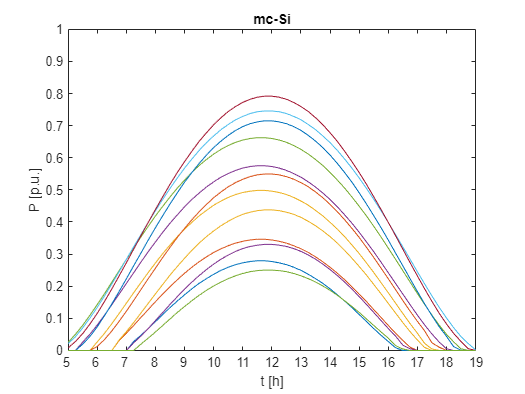

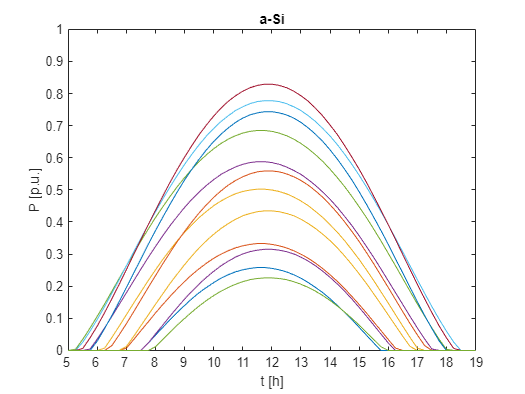

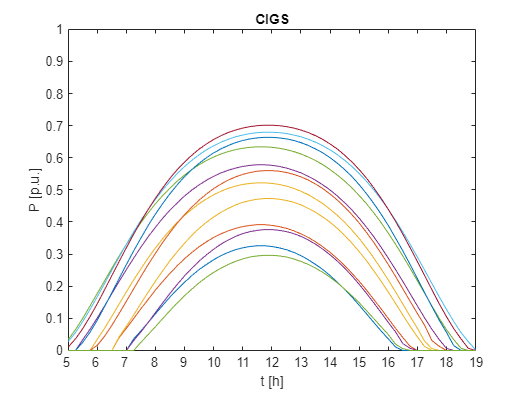

%%
Pn = 1;
for i = 1:1:3,
    prod_p = P_pv(Irr_PA_mon,k(i,:),Pn,rend_PV);
    figure
    plot(prod_p)
    set(gca,'YLim',[0 Pn])
    set(gca,'XLim',[1 size(Irr_PA_mon,1)])
    set(gca,'XTick',[1:4:57])
    set(gca,'XTickLabel',[5:1:19])
    xlabel('t [h]')
    ylabel('P [p.u.]')
    title(tech(i))
end

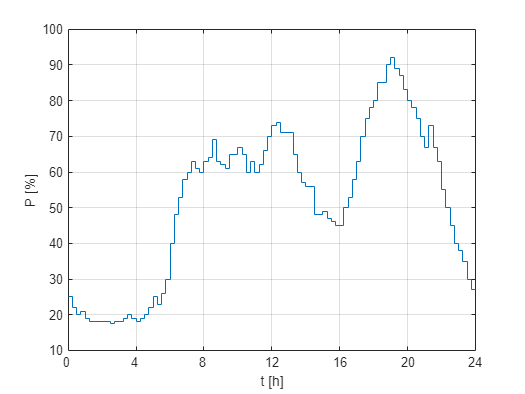

%%
figure
stairs([residential;residential(end)])
set(gca,'XLim',[1 length(residential)+1]);
set(gca,'XTick',[1,(4*4+1):4*4:96,97]);
set(gca,'XTickLabel',[0:4:24]);
xlabel('t [h]')
ylabel('P [%]')
grid on

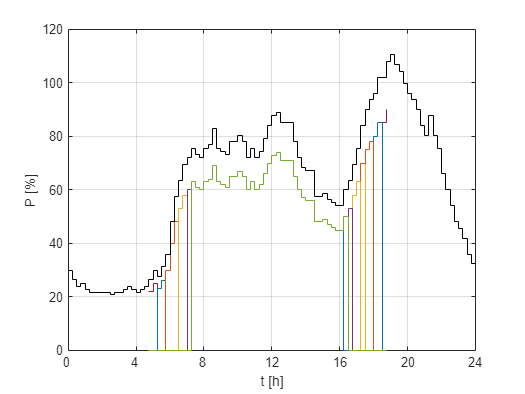

figure
stairs([residential;residential(end)])
set(gca,'XLim',[1 length(residential)+1]);
set(gca,'XTick',[1,(4*4+1):4*4:96,97]);
set(gca,'XTickLabel',[0:4:24]);
xlabel('t [h]')
ylabel('P [%]')
grid on
%% irradiance is in [5am,7pm]
res_load_pu = repmat(residential(start_time*4:1:end_time*4),1,12);
res_load_pu(Irr_PA_mon == 0) = zeros(size(find(Irr_PA_mon == 0)));
figure
stairs([start_time*4:1:(end_time*4)],res_load_pu)
hold on
stairs([residential;residential(end)].*1.2,'k')
set(gca,'XLim',[1 length(residential)+1]);
set(gca,'XTick',[1,(4*4+1):4*4:96,97]);
set(gca,'XTickLabel',[0:4:24]);
xlabel('t [h]')
ylabel('P [%]')
grid on
hold off

res_load = res_load_pu.*P_load./100;
%%
irr = reshape(Irr_PA_mon,[],1);
p_load = reshape(res_load,[],1);

options = optimoptions('fmincon','Algorithm','interior-point','Display','none');
self_cons_thres = [.5 .6 .7 .8 .9 1];
for ii = 1:length(tech),
    for jj = 1:length(self_cons_thres),
        tic
        [y(ii,jj), fval, exitflag(ii,jj)] = fmincon(@(x) -x, 1,[],[],[],[],0,[],@(x) mycon(x,p_load,irr,k(ii,:),rend_PV,self_cons_thres(jj)),options);
        etime(ii,jj) = toc;
    end
end
clear fval

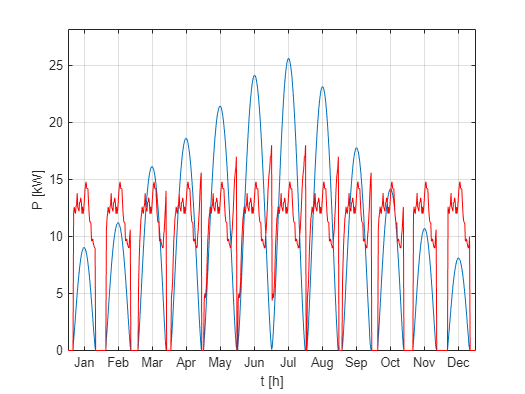

a = datenum('01/01/2017');
for i = 1:12,
    [n , month_label{i}] = month(a + 31*(i-1));
end
clear a
tech_sel = 1;
% self_cons_thres = [.5 .6 .7 .8 .9 1];
self_cons_comp = [.8 1];
figure
plot(P_pv(irr,k(tech_sel,:),y(tech_sel,find(self_cons_thres == self_cons_comp(1))),rend_PV)./1e3)
hold on
plot(p_load./1e3,'r')
set(gca,'XLim',[1 length(p_load)]);
set(gca,'YLim',[0 1.1*max(max(P_pv(irr,[-0.0138 0.000898 0],y(tech_sel,find(self_cons_thres == self_cons_comp(2))),rend_PV)),max(P_pv(irr,k(tech_sel,:),y(tech_sel,find(self_cons_thres == self_cons_comp(1))),rend_PV)))]/1e3)
set(gca,'XTick',[28:57:12*57]);
set(gca,'XTickLabel',month_label);
xlabel('t [h]')
ylabel('P [kW]')
grid on
hold off

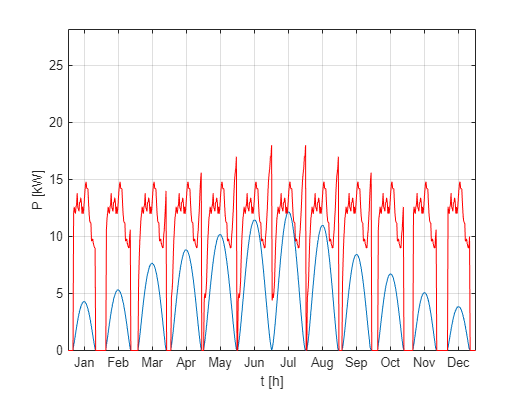

figure
plot(P_pv(irr,k(tech_sel,:),y(tech_sel,find(self_cons_thres == self_cons_comp(2))),rend_PV)./1e3)
hold on
plot(p_load./1e3,'r')
set(gca,'XLim',[1 length(p_load)]);
set(gca,'YLim',[0 1.1*max(max(P_pv(irr,k(tech_sel,:),y(tech_sel,find(self_cons_thres == self_cons_comp(2))),rend_PV)),max(P_pv(irr,k(tech_sel,:),y(tech_sel,find(self_cons_thres == self_cons_comp(1))),rend_PV)))]/1e3)
set(gca,'XTick',[28:57:12*57]);
set(gca,'XTickLabel',month_label);
xlabel('t [h]')
ylabel('P [kW]')
grid on
hold off

for jj = 1:length(self_cons_thres),
    for ii = 1:length(tech),
        a = P_pv(irr,k(ii,:),y(ii,jj),rend_PV) - p_load;
        a(a<0) = zeros(size(find(a<0)));
        max_P_stg(ii,jj) = max(a)/1e3;
        max_E_stg(ii,jj) = max(sum(reshape(a,size(Irr_PA_mon)))./4)/1e3;
        clear a
    end
end

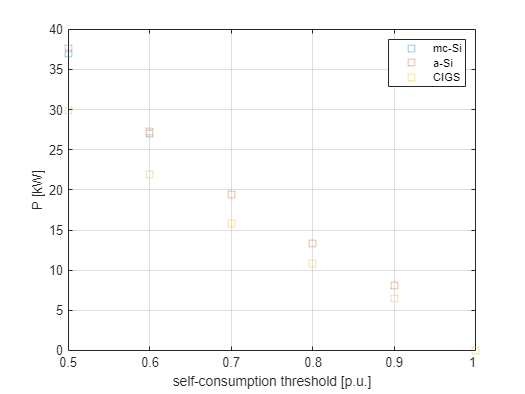

figure
plot(max_P_stg','Marker','s','MarkerSize',7,'LineStyle','none')
legend(tech)
set(gca,'XTick',[1:1:length(self_cons_thres)])
set(gca,'XTickLabel',self_cons_thres)
xlabel('self-consumption threshold [p.u.]')
ylabel('P [kW]')
grid on

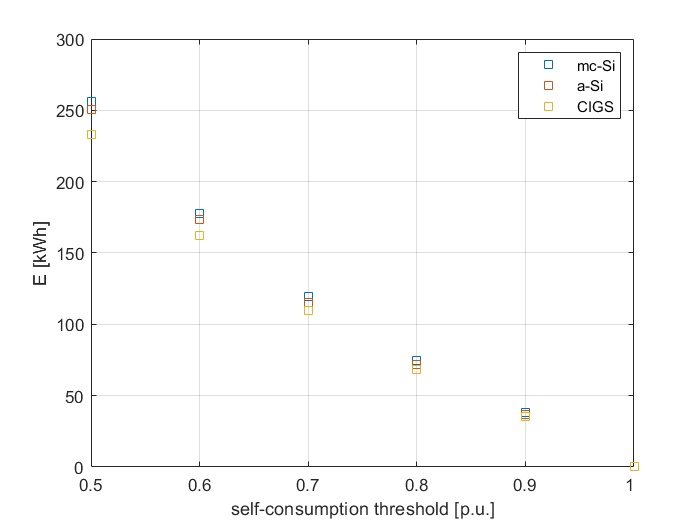

figure
plot(max_E_stg','Marker','s','MarkerSize',7,'LineStyle','none')
legend(tech)
set(gca,'XTick',[1:1:length(self_cons_thres)])
set(gca,'XTickLabel',self_cons_thres)
xlabel('self-consumption threshold [p.u.]')
ylabel('E [kWh]')
grid on